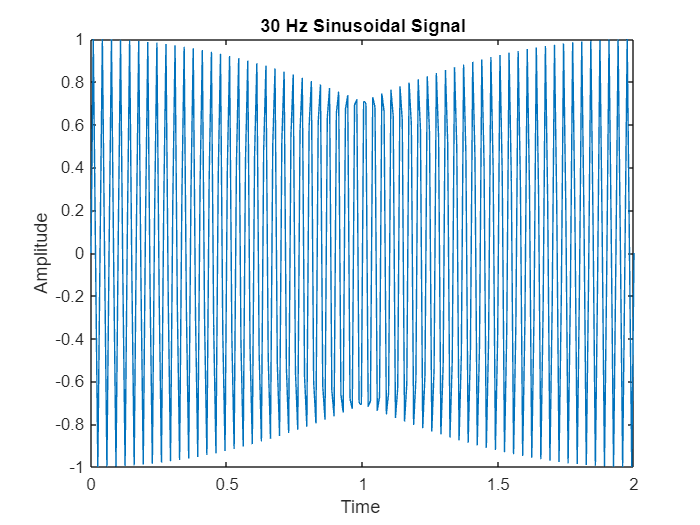

f = 30;     
duration = 2;        
sampling_rate = 120; 


samples = duration * sampling_rate;


time= linspace(0,2,240);


amplitude = 1; 
signal = amplitude * sin(2 * pi * f * time);


plot(time_vector, signal);
xlabel('Time ');
ylabel('Amplitude');
title('30 Hz Sinusoidal Signal');

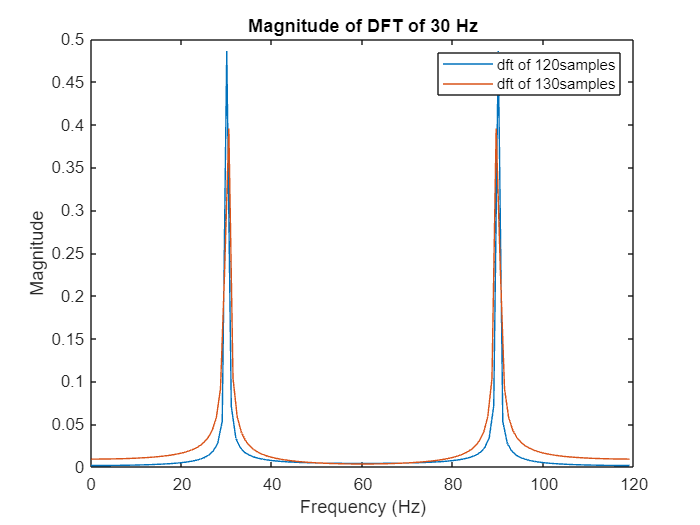

f = 30;      
d = 2;        
sampling_rate = 120; 


samples = d * sampling_rate;


time = linspace(0, 2, 240);

amplitude = 1; 
signal = amplitude * sin(2 * pi * f* time);


N1 = 120;
dft_result1 = fft(signal(1:N1));


frequencies1 = (0:N1-1) * (sampling_rate / N1);


magnitude1 = abs(dft_result1);




N2 = 130;
dft_result2 = fft(signal(1:N2));


frequencies2 = (0:N2-1) * (sampling_rate / N2);


magnitude2 = abs(dft_result2);
y1=plot(frequencies1, magnitude1/N1);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude of DFT of 30 Hz');
hold on

y2=plot(frequencies2, magnitude2/N2);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude of DFT of 30 Hz');
legend([y1 y2],'dft of 120samples','dft of 130samples')
hold off

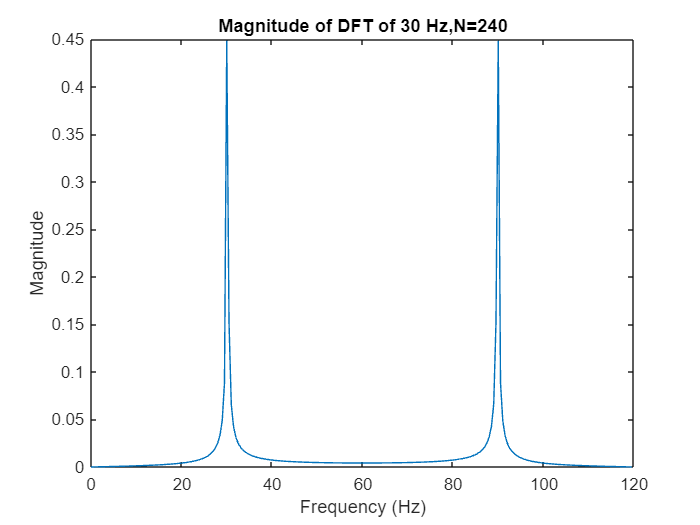

f = 30;      
d = 2;        
sampling_rate = 120; 


samples = d * sampling_rate;


time = linspace(0, 2, 240);

amplitude = 1; 
signal = amplitude * sin(2 * pi * f* time);


N1 = 240;
dft_result1 = fft(signal(1:N1));


frequencies1 = (0:N1-1) * (sampling_rate / N1);


magnitude1 = abs(dft_result1);
plot(frequencies1, magnitude1/N1);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude of DFT of 30 Hz,N=240');

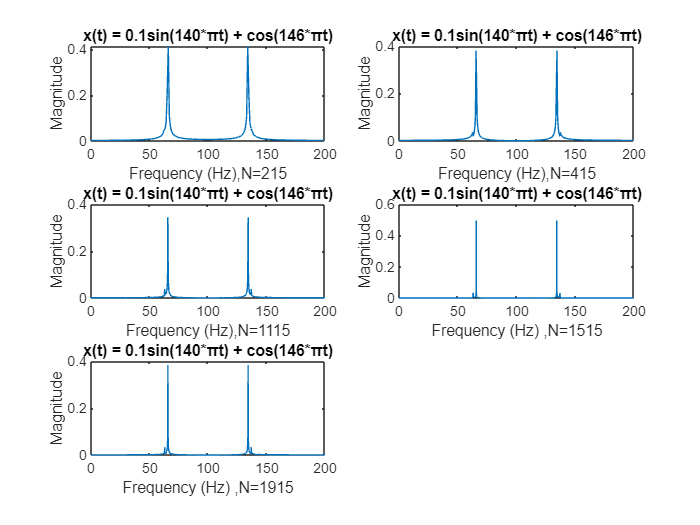

a=2;
A=140;
B=146;
sampling_rate=200;
duration=10;
samples=sampling_rate*duration;
t=linspace(1,10,2000);

N3 = 215;
xa=0.1.*(sin(A*pi*t))+cos(B*pi*t);
dft_result3 = fft(xa(1:N3));
frequencies3 = (0:N3-1) * (sampling_rate / N3);
magnitude3 = abs(dft_result3);
subplot(3,2,1)
plot(frequencies3, magnitude3/N3);
xlabel('Frequency (Hz),N=215');
ylabel('Magnitude');
title('x(t) = 0.1sin(140*πt) + cos(146*πt)')

N4 = 415;
xa=0.1.*(sin(A*pi*t))+cos(B*pi*t);
dft_result4= fft(xa(1:N4));
frequencies4 = (0:N4-1) * (sampling_rate / N4);
magnitude4 = abs(dft_result4);
subplot(3,2,2)
plot(frequencies4, magnitude4/N4);
xlabel('Frequency (Hz),N=415');
ylabel('Magnitude');
title('x(t) = 0.1sin(140*πt) + cos(146*πt)')

N5 = 1115;
xa=0.1.*(sin(A*pi*t))+cos(B*pi*t);
dft_result5= fft(xa(1:N5));
frequencies5 = (0:N5-1) * (sampling_rate / N5);
magnitude5 = abs(dft_result5);
subplot(3,2,3)
plot(frequencies5, magnitude5/N5);
xlabel('Frequency (Hz),N=1115');
ylabel('Magnitude');
title('x(t) = 0.1sin(140*πt) + cos(146*πt)')

N6 = 1515;
xa=0.1.*(sin(A*pi*t))+cos(B*pi*t);
dft_result6= fft(xa(1:N6));
frequencies6 = (0:N6-1) * (sampling_rate / N6);
magnitude6 = abs(dft_result6);
subplot(3,2,4)
plot(frequencies6, magnitude6/N6);
xlabel('Frequency (Hz) ,N=1515');
ylabel('Magnitude');
title('x(t) = 0.1sin(140*πt) + cos(146*πt)')

N7 = 1915;
xa=0.1.*(sin(A*pi*t))+cos(B*pi*t);
dft_result7= fft(xa(1:N7));
frequencies7 = (0:N7-1) * (sampling_rate / N7);
magnitude7 = abs(dft_result7);
subplot(3,2,5)
plot(frequencies7, magnitude7/N7);
xlabel('Frequency (Hz) ,N=1915');
ylabel('Magnitude');
title('x(t) = 0.1sin(140*πt) + cos(146*πt)')

hold off

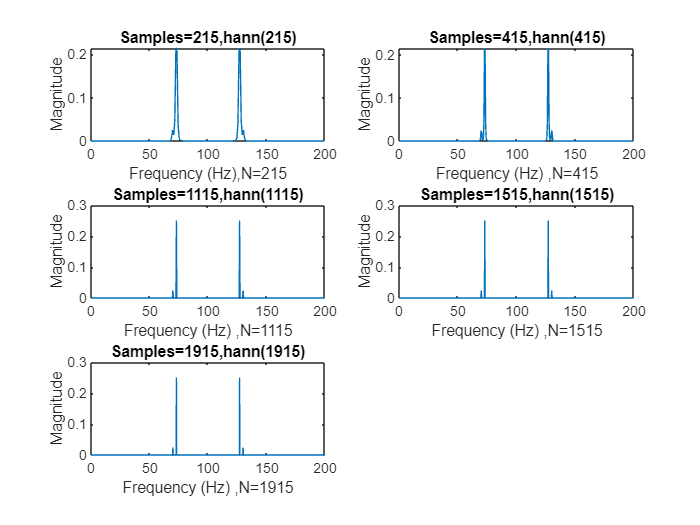


A=140;
B=146;
sampling_rate=200;
duration=10;
samples=sampling_rate*duration;
t1=0:1/200:(214/200);
N3a = 215;
xa1=(0.1.*sin(A*pi*t1)+cos(B*pi*t1)).*(transpose(hann(215)));
dft_result3a = fft(xa1);
frequencies3a = (0:N3a-1)* (sampling_rate / N3a);
magnitude3a = abs(dft_result3a);
subplot(3,2,1)
plot(frequencies3a, magnitude3a/N3a);
xlabel('Frequency (Hz),N=215');
ylabel('Magnitude');
title('Samples=215,hann(215)')

t2=0:1/200:(414/200);
N4a = 415;
xa2=(0.1.*sin(A*pi*t2)+cos(B*pi*t2)).*(transpose(hann(415)));
dft_result4a = fft(xa2);
frequencies4a = (0:N4a-1)* (sampling_rate / N4a);
magnitude4a = abs(dft_result4a);
subplot(3,2,2)
plot(frequencies4a, magnitude4a/N4a);
xlabel('Frequency (Hz) ,N=415');
ylabel('Magnitude');
title('Samples=415,hann(415)')

t3=0:1/200:(1114/200);
N5a = 1115;
xa3=(0.1.*sin(A*pi*t3)+cos(B*pi*t3)).*(transpose(hann(1115)));
dft_result5a = fft(xa3);
frequencies5a = (0:N5a-1)* (sampling_rate / N5a);
magnitude5a = abs(dft_result5a);
subplot(3,2,3)
plot(frequencies5a, magnitude5a/N5a);
xlabel('Frequency (Hz) ,N=1115');
ylabel('Magnitude');
title('Samples=1115,hann(1115)')

t4=0:1/200:(1514/200);
N6a = 1515;
xa4=(0.1.*sin(A*pi*t4)+cos(B*pi*t4)).*(transpose(hann(1515)));
dft_result6a = fft(xa4);
frequencies6a = (0:N6a-1)* (sampling_rate / N6a);
magnitude6a = abs(dft_result6a);
subplot(3,2,4)
plot(frequencies6a, magnitude6a/N6a);
xlabel('Frequency (Hz) ,N=1515');
ylabel('Magnitude');
title('Samples=1515,hann(1515)')

t5=0:1/200:(1914/200);
N7a = 1915;
xa5=(0.1.*sin(A*pi*t5)+cos(B*pi*t5)).*(transpose(hann(1915)));
dft_result7a = fft(xa5);
frequencies7a = (0:N7a-1)* (sampling_rate / N7a);
magnitude7a = abs(dft_result7a);
subplot(3,2,5)
plot(frequencies7a, magnitude7a/N7a);
xlabel('Frequency (Hz) ,N=1915');
ylabel('Magnitude');
title('Samples=1915,hann(1915)')

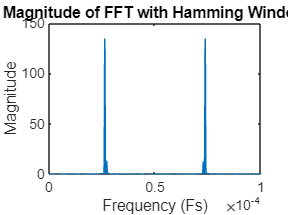


data = load('Exp4Data2.txt');
Fs = 1; 
T=1/Fs;
t=0:T:duration-T;
N = length(data);

%4(a)
window = hamming(N);
data_window = data .* window';

n= 10000;
fft_new = fft(data_window, n);
freq = (0:n-1) * (Fs / n);
freq_normalized = freq / n;
figure;
plot(freq_normalized, abs(fft_new));
title('Magnitude of FFT with Hamming Window');
xlabel('Frequency (Fs)');
ylabel('Magnitude');


[~, max_indices] = maxk(abs(fft_new), 2);
frequencies = freq_normalized(max_indices);
disp(['Estimated Frequencies using Hamming Window: ', num2str(sort(frequencies))]);

Estimated Frequencies using Hamming Window: 2.632e-05   7.368e-05


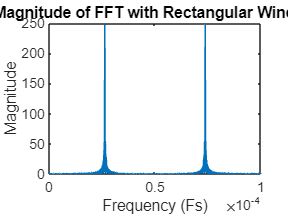


%4(b)
window_rect = rectwin(N);
data_window_rect = data .* window_rect';
fft_rect = fft(data_window_rect, n);
figure;
plot(freq_normalized, abs(fft_rect));
title('Magnitude of FFT with Rectangular Window');
xlabel('Frequency (Fs)');
ylabel('Magnitude');


[~, max_indices] = maxk(abs(fft_rect), 2);
frequencies1 = freq_normalized(max_indices);
disp(['Estimated Frequencies using Rectangular Window: ', num2str(sort(frequencies1))]);

Estimated Frequencies using Rectangular Window: 2.632e-05   7.368e-05
